# Geoscience Data Analysis

*D. Hasterok (derrick.hasterok@adelaide.edu.au)*

*Dept. of Earth Sciences, University of Adelaide, North Terrace, Adelaide, SA 5005*

# 6 Regression Analysis

addpath ../codes
addpath ../data

clear all;

## 6.1 Introduction

To a geophysicist, we often refer to regression as inversion theory.  To mathematicians and physicists it may be called parameter optimization.  But to most scientists, economists, and statisticians, curve fitting is simply known as regression analysis, or just regression.  In this chapter, we'll look at how to fit models to data and quantify their uncertainties.  We'll start with simply fitting lines to data and move on to multidimensional and non-linear problems.

But before we get started, I want to consider the importance of understanding your data before you blindly try to fit a line.  While we use mathematics and statistics to develop our descriptive models for data, we cannot neglect our own observations.  We will examine 4 artificial datasets all with nearly identical statistical characteristics and linear fits, but as you will see are all very different in character.  The datasets are known as Anscombe's quartet and were devised to highlight the importance of looking at data before modeling.

clear all;

% Anscombe's quartet
t = readtable('Anscombe_quartet.csv','Format','%f%f%f%f%f%f%f%f')

t = 11×8 table
    x1     y1      x2     y2     x3     y3      x4     y4 
    __    _____    __    ____    __    _____    __    ____

    10     8.04    10    9.14    10     7.46     8    6.58
     8     6.95     8    8.14     8     6.77     8    5.76
    13     7.58    13    8.74    13    12.74     8    7.71
     9     8.81     9    8.77     9     7.11     8    8.84
    11     8.33    11    9.26    11     7.81     8    8.47
    14     9.96    14     8.1    14     8.84     8    7.04
     6     7.24     6    6.13     6     6.08     8    5.25
     4     4.26     4     3.1     4     5.39    19    12.5
    12    10.84    12    9.13    12     8.15     8    5.56
     7     4.82     7    7.26     7     6.42     8    7.91
    


% first the statistics of the data
% the columns are in pairs of x and y values
for i = 1:4
    x = t{:,2*i-1};
    y = t{:,2*i};

    stats(i).x_mean = mean(x);
    stats(i).x_std = std(x);
    
    stats(i).y_mean = mean(y);
    stats(i).y_std = std(y);
    
    % compute correlation coefficient
    C = corrcoef(x,y);
    stats(i).correlation = C(2,1);
    
    % fit a line to the data
    p = polyfit(x,y,1);
    stats(i).slope = p(1);
    stats(i).intercept = p(2);
    
    stats(i).r_squared = stats(i).correlation^2;
end

% make a table with the statistical analysis of the four datasets
struct2table(stats)

ans = 4×8 table
    x_mean    x_std     y_mean    y_std     correlation     slope     intercept    r_squared
    ______    ______    ______    ______    ___________    _______    _________    _________

      9       3.3166    7.5009    2.0316      0.81642      0.50009     3.0001       0.66654 
      9       3.3166    7.5009    2.0317      0.81624          0.5     3.0009       0.66624 
      9       3.3166       7.5    2.0304      0.81629      0.49973     3.0025       0.66632 
      9       3.3166    7.5009    2.0306      0.81652      0.49991     3.0017       0.66671 


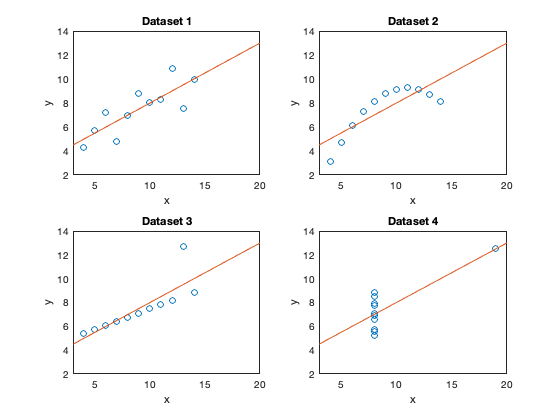

% plot the linear fit to each dataset
figure;
for i = 1:4
    x = t{:,2*i-1};
    y = t{:,2*i};
    
    subplot(2,2,i);
    hold on;
    plot(x,y,'o');
    
    xl = [3 20];
    yl = stats(i).slope*xl + stats(i).intercept;
    plot(xl,yl,'-');
    
    xlabel('x');
    ylabel('y');
    title(['Dataset ',num2str(i)])
    axis([xl 2 14]);
    set(gca,'Box','on');
end

As you can see, all four of these datasets have the same basic statistics and yet they are all *very* different.  The linear fit to the first dataset is reasonable, but a linear model is not appropriate for the second, a parabola will provide a more accurate description of the data.  A linear model is appropriate for the third dataset, but there is an outlier that must be dealt with.  The fourth dataset is may not be correlated, only giving the appearance of linear correlation because of the one data point has such high leverage.

The main point is that whatever analysis you do and statistics you calculate, you still need to use your own judgement to interpret the validity of the result, and the appropriate visual display of data is key.

## 6.2 Measures of Misfit

When developing a physical model, we need a way to discriminate whether it's ability to match the data is better or worse than other alternative models we may create.  In general, we are looking for a single number to characterize the misfit between data and a model.  The way in which we define the misfit (metric) will affect the inversion results, sometimes quite dramatically.  In selecting our metric, we impart our biases, prior knowledge, and uncertainties in the data and/or model.

### 6.2.1 Norms

We sometimes refer to the misfit as the model norm, with two norms forming the basis of most misfit functionals.\footnote{A functional is simply a function that takes vectors as an argument and returns a single scalar value.}  We have already used norms at various times---magnitude of vectors, magnitude of complex numbers, and distance between points.  All of these examples are considered $L^2$-norms (also called Euclidean norm) and are given by


$$||{\bf x}||_2 = \left( \sum_{i=1}^N x_i^2 \right)^{1/2}$$


The vector, $\bf x$, could represent the distance between two vectors, Cartesian points, or as you will see in our case, the observed data and modeled data vectors.  We can also write the $L^2$-norm in vector form as

$||{\bf x}||_2 = ({\bf x}^{\text{T}} {\bf x})^{1/2}$ ,

where ${\bf x}^\text{T}$ is the transpose of ${\bf x}$.

A second, and somewhat simpler $L^1$-norm is also commonly used:


$$||{\bf x}||_1 = \sum_{i=1}^N |x_i|$$


It has the advantage that it is less susceptible to extreme outliers in the data than the $L^2$-norm.  If you are trying to automate a process, you might not use an $L^1$-norm so there is less of a need to clean the data of outliers first.

We can develop higher order norms, but these are the two most commonly used, so we will leave off here.

### 6.2.2 Basic Misfit Functionals

One of the most common misfit functionals is the ***root-mean-square (RMS) misfit***,

defined by


$$\phi_2 = \left( \frac{1}{N_d}\sum_{i=1}^{N_d} (d_i - \hat{d}_i)^2 \right)^{1/2}$$


where $N_d$ is the number of data points being fit.  The RMS is an arithmetic mean of the differences between the individual observed data points $d_i$ and modeled data points $\hat{d}_i$.  Note this is for an $L^2$-norm.

A similar $L^1$-norm misfit yields the median rather than mean of the differences,


$$\phi_1 = \frac{1}{N_d} \sum_{i=1}^{N} |d_i - \hat{d}_i|$$


An $L^1$-norm is commonly used when locating earthquakes.

### 6.2.3 Normalized RMS Misfit

Both of these basic misfit functionals fail to incorporate data uncertainties.  To do so, we can simply add weights for each on each data point into the basic RMS equation by


$$\phi_2 = \left( \frac{1}{N_d} \sum_{i=1}^{N_d} w_i (d_i - \hat{d}_i)^2 \right)$$


Generally, we wish to weight our data by the inverse of their variance, $w_i = \sigma_i^{-2}$, giving additional weight to data with low variance and reducing the weight of data with high variance.


$$\phi_2 = \left( \frac{1}{N_d} \sum_{i=1}^{N_d} \frac{(d_i - \hat{d}_i)^2}{\sigma_i^2} \right)^{1/2}$$


We will call this expression the normalized misfit.

### 6.2.4 Chi-squared $(\chi^2)$

Another misfit that is commonly used is the Chi-squared, $\chi^2$, misfit,


$$\chi^2 = \sum_{i=1}^{N_d} \frac{(d_i - \hat{d}_i)^2}{\sigma_i^2}$$


As we proceed you will see more and more matrix notation being used.  We can also write $\chi^2$ as


$$\chi^2 = ({\bf d} - {\bf \hat{d}})^\text{T} {\bf W_d}^2 ({\bf d} - {\bf \hat{d}})$$


where ${\bf W_d}$ is a diagonal matrix with the $i$-th diagonal $\sigma_i^{-1}$.

We can normalize the $\chi^2$-squared statistic by the number of degrees of freedom to arrive at the reduced $\chi^2_\nu$ statistic (also known as the mean square weighted deviation or MSWD),


$$\chi_\nu^2 = \frac{1}{\nu} \sum_{i=1}^{N} \frac{(d_i - \hat{d}_i)^2}{\sigma_i^2}$$


where $\nu$ is the number of degrees of freedom $N_d-N_m$ is the number of degrees of freedom (number of data minus the number of model parameters).  If the number of model parameters is small compared with the number of data used to constrain it, then the $N_d-N_m \approx N_d$ and $\chi_\nu^2$ closely resembles the square of the RMS.  The MSWD is the commonly used term in geochronology (e.g., IsoplotR, Vermeesch, 2018).

## 6.3 Inversion

### 6.3.1 Challenges with Inverting

Many problems in geophysics—science in general—are under-determined, non-unique and unstable.  What do I mean by this? Typically, inversion problems are

**    under-determined**, we do not have enough data to properly characterize the system;

**    non-unique**, more than one, and possibly an infinite number of models can fit the available data; and 

**    unstable**, the process of estimating a model can be difficult to obtain due to numerical instabilities leading to spurious or non-convergent solutions.

With all those difficulties, how do we actually obtain a meaningful result?

A word of caution: As you will see below, there are a lot of dials and switches that we can use to tune our inversion models.  One must be careful using these controls so that the model remains both meaningful and accurate.

Without a thorough understanding how these controls influence the model mathematically, it is easy to make mistakes that yield a result that may look good and validate our preconceived notions of Earth's structure, composition, and properties but may be incorrect.  Most inversion models must be tested for sensitivity and reliability using a variety of tests often tailored to the method and model output.  Although we won't go into sensitivity testing, I want you to be aware that just because you have produced a model that fits the data, you are not done modeling.  We often produce tens to hundreds of models on the way to producing one that shows up in a publication.

### 6.3.2 Under- vs. Over-determined

The first course of action is to turn our under-determined problem into an over-determined problem so that we have more data than model parameters that we are trying to find.  We can do so by limiting the number of model parameters.

For example, suppose we wanted to model the density variations giving rise to an observed gravity field across a mountain range to locate an ore body.  Now imagine the rocks below the surface down to the grain scale.  Each individual grain has its own density and the rock itself has some degree of void space either unfilled or filled with some fluid and associated density.  Modeling this scale of density variations from surface gravity measurements is guaranteed to be under-determined.  However, the density of a handheld specimen of rock represents the effective density of the collection of minerals and fluid and/or void space that make up the rock.  This is still too small a scale, but as we increase the scale to outcrop and up to rock unit, we begin to see that we can perhaps represent the density of a much larger volume by a single value—assuming relative homogeneity on a large scale.  Hence by limiting ourselves to sufficiently large volumes represented by a single value we dramatically reduce the number of free model parameters turning an under-determined problem into an over determined one.

### 6.3.3 Uniqueness

A unique model occurs when there is only one solution that fits the data. However, consider the equation $y = x^2$.  For every $x$ value there is exactly one $y$.  But if you invert the equation $x = \sqrt{y}$, there are multiple solutions, e.g. if $y = 4$, $x = \pm 2$.  This example is a fairly explicit example of a non-unique solution, but there many cases were non-uniqueness is more subtle.  And when the data are uncertain, there may be an infinite number of models which fit the data to the same level of misfit.

Non-uniqueness can also arise from a lack of sensitivity to certain parameters.  For example, the magnetotelluric method is a geophysical technique that uses variations in the long-wavelength electromagnetic field to investigate the Earth's interior.  The fields that are recorded at the surface result from the variations in the electrical conductivity in the subsurface, but the physics presents some sensitivity problems.  The method is sensitive to the combination of the size and conductivity of a conductive body, but neither independently.  As a result a large range of conductivities are acceptable to the model, but of course only one is correct.  We can't change physics, so how can we address the ambiguity?

The shape of a misfit functional is generally smooth but can have complexities as the model parameters change resulting in surfaces or curves that have multiple local minima (Figure 1).  Inversions which are iterative can get stuck within a local minima, unable to access regions with lower misfit.  Using multiple initial conditions for an inversion can occasionally help move the solution from one minima to another, but how do we tell which one is correct, certainly both cannot?  Simply choosing the lowest misfit may not be appropriate as we may be constrained by data uncertainties or the global minima may result in "over-fitting" the observed data.

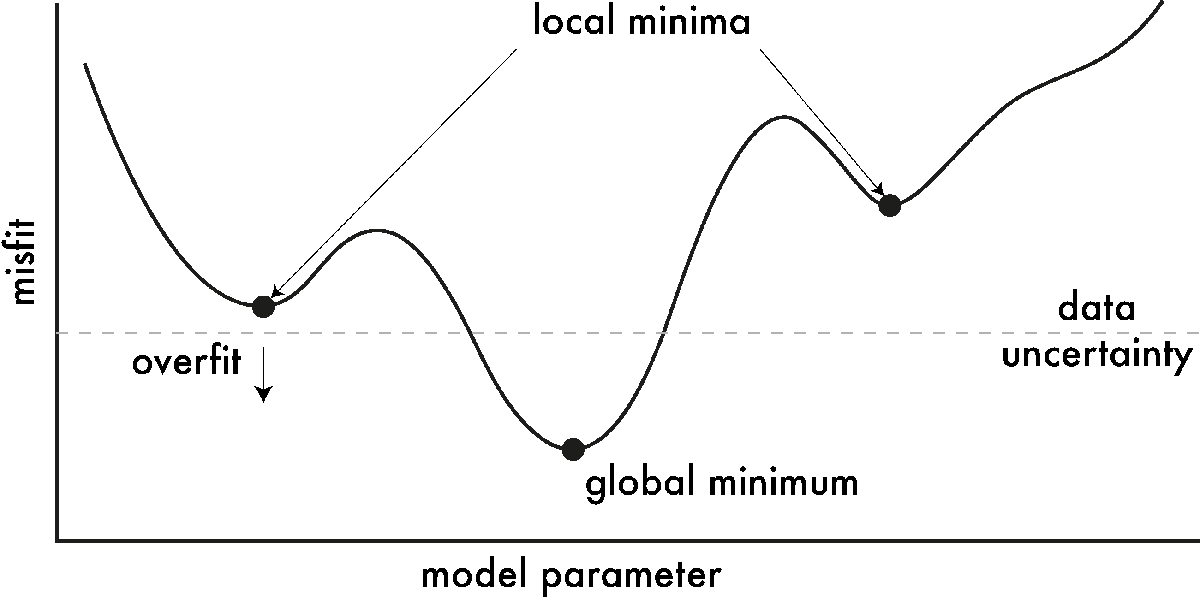

**Figure 1** – *Hypothetical misfit function.  Each point on the misfit curve represents a unique set of model parameters.  A misfit function may have multiple local minima in addition to a global minimum.  Models which sit below the data uncertainty overfit the data.*

In some cases, it may be possible to improve sensitivity by collecting additional data that fill strategic gaps.  Adding additional constraints can reduce non-uniqueness, either adding another type of data with different sensitivities or geological constraints.  It may also be possible to place constraints on the solution, e.g., only positive values or within a common range.

### 6.3.4 Stability

Inversion problems are notoriously unstable.  Given the wrong initial condition "far" from a solution may result in each successive iterative step moving increasingly further from a viable solution.  Basically the model spins out of control and the inversion will not converge.  Hence, the initial condition can affect not only the solution, but also the stability.  Another problem that can arise are models in which the values of adjacent cells increasing grow in opposite directions such that their average response at the surface may be approximately the same, but the two values are increasingly divergent.  For example, imagine a resistivity cross-section that looks more like a checkerboard pattern of conductive and resistive squares rather than a geologically plausible image.  I've classified this problem as a stability issue, but it could as easily be classified as non-uniqueness as the misfit may reduce as this occurs suggesting the model fits the data but is clearly geologically implausible.

We can attempt to stabilize these problems by penalizing the misfit functional in various ways.  That is, the misfit will grow if the model strays too far from our imposed constraint in an attempt to force the inversion to take steps towards a reasonable solution rather than running away.  An analogy that sort of works is to imagine a goat tethered to a tree.\footnote{This analogy comes from a very Russian professor, Mikhail Zhdanov, I had as a graduate student at the University of Utah.  Most of us would probably think of a tethered dog, but a goat somehow makes it so much more memorable.}  The goat can wander (misfit) anywhere between the tree and the maximum length of the rope (penalty); assuming of course that the goat doesn't eat the rope or the tree (we can only take analogies so far).  Adding these penalties doesn't always work, but it does tend to significantly improve the stability.

A penalty for straying too far from a prescribed model is perhaps the most closely aligned with our goat on a rope analogy.  This type of penalty best prevents the instabilities that allow models which cause misfit to grow uncontrollably.  To limit the "checkerboard" problem above, we can penalize the model roughness, forcing models to be smoothly varying.  The price we pay for smoothing is a difficulty in resolving boundaries that represent a step change in a model property (e.g., seismic velocity contrast between two layers).  However, there are additional method to still allow for discontinuities under certain conditions.

In addition to the stability concerns addressed above, inversions can be made unstable by the presence of a data outlier or even perhaps the smaller noisy variations in the data resulting from measurement uncertainties.  This effect can be mitigated by weighting the data by its certainty (inverse of the uncertainty) as we estimate the misfit.

### 6.3.5 Inversion Recipes

Before formulating an inverse problem, we need to know how to formulate the forward problem.  We can summarize forward problems by


$$A_{\text{physics}} m_{\text{physical properties}} = d_{\text{fields}}$$


While the equation above hides much of the complexities involved in the forward solution, it captures the similarity of the process that we can follow for nearly all of our geophysical inverse problems.  The mathematical description of the physical process is contained within $A$, which is typically called the forward operator.  This operator contains the `rules' of the system under investigation, telling us how changes in Earth's physical properties and source geometry affect the strength of the fields that we measure.  The physical properties of Earth (the model parameters) are contained within $m$ and the observed fields (data) are denoted by $d$.

Since we observe $d$, we can invert for $m$ by


$${\bf m} = {\bf A}^{-1} {\bf d}$$


However, it is typically not this simple because there is often no easy way to invert ${\bf A}$.  In order to invert ${\bf A}$, ${\bf A}$ must be a square matrix (same number of rows and columns) and non-singular. A singular matrix occurs when the determinant is 0. Generally, we have more data than model parameters, resulting in more equations than unknowns.  Since ${\bf A}$ is not square, we need ways to approach the problem.  In the subsections below, we will focus on two common approaches to solving the above equation for $m$ without taking the inverse of ${\bf A}$ directly.  In Section 6.4, we will look at the linear least squares method, a common approach when the physical problem can be linearized.  And in Section 6.6.2, we will derive use an approach based on the Newton–Raphson method for finding roots to functions.

## 6.4 Linear Least Squares

### 6.4.1 Fitting a line

Fitting lines and polynomials to data are one of the most common practices to interpreting data in many fields of science and social science.  Most of you may be familiar with the functions that are used within a spreadsheet or other program but may not know what it is doing behind the scenes.  Fitting a line to data is an inverse problem.

Imagine we have collected number of data (N points in all) at known locations,

$x = x_1,x_2,\ldots,x_N$, resulting in observations with values, $y = y_1,y_2,\ldots,y_N$.  Assuming the data appear sufficiently linear we wish to fit a single line to all the data.  We will need to determine a slope, $m$, and intercept, $b$, which are our model, i.e., $y = m x + b$.  Simply fitting the data by eye won't cut it since it isn't sufficient to produce the 'best'-fitting model.

We could try a range of slopes and intercepts and pick the pairs systematically or randomly) and determine the one which provides the minimum misfit to the data.  Testing sets of parameters in this way is called a grid search and is really multiple applications of the forward problem.  A grid search can be useful for mapping out the misfit surface and illustrating the sensitivities to different model parameters.  However, grid searching can be very time consuming.  Instead, we would rather have a way to identify the best possible model in one step.

One approach to identify the minimum misfit by directly computing the best-fitting model parameters.  The method below is called the linear least squares (LLSQ) because it minimizes the misfit of the squared difference between the data and predicted data.  Suppose we collect observations at known locations $x = x_1,x_2,\ldots,x_N$.  We choose a slope, $m$, and intercept, $b$, which yield the modeled data, $\hat{y_i}$,


$$\hat{y}_1 = m x_1 + b$$



$$\hat{y}_2 = m x_2 + b$$



$$\vdots$$



$$\hat{y}_N = m x_N + b$$


which we can generalize as $\hat{y}_i = m x_i + b$, where $x_i$ and $\hat{y}$ are the location and estimate of the $i$-th data point.  The squared misfit of the $i$-th data point is given by,


$$\phi_i = \sqrt{(y_i - \hat{y}_i)^2}$$


This individual misfit can be positive or negative indicating whether the model point is below or above the measured point.  However, we care about the total misfit (unsigned distance) from each point which is given by


$$\phi^2 = \sum_{i = 1}^N (y_i - \hat{y}_i)^2$$


Note this is an $L^2$-norm.

The minimum misfit for the $i$-th data point is a model that passes through the point $(x_i, y_i)$; though the best-fitting model for all of the data may not have a zero misfit at any given observation.  Therefore, we need to identify the set of model parameters ($m$ and $b$ in this case) which collectively provides the minimum misfit to the observations.  Since we are looking for a minimum we need to determine the derivative (set to zero) and since we have multiple model parameters we'll determine the minimum with respect to each model parameter (using partial derivatives). The minimum misfit with respect to slope is


$$\frac{\partial \phi^2}{\partial m} = 0 = \frac{\partial}{\partial m} \left(\sum_{i = 1}^N (y_i - \hat{y}_i)^2 \right)$$



$$0 = -2 \sum (y_i - \hat{y}_i) \frac{\partial \hat{y}_i}{\partial m}$$



$$0 = \sum [y_i - (m x_i + b)] \frac{\partial (m x_i + b)}{\partial m}$$



$$0 = \sum [y_i - (m x_i + b)] x_i$$


which we can reorder as


$$0 = \sum_{i = 1}^N y_i x_i - m \sum_{i = 1}^N x_i^2 - b \sum_{i = 1}^N x_i$$


(note: since the limits on all the sums are $i \ldots N$, I drop them on all the intermediate steps to reduce clutter.  Following a similar procedure for the intercept,


$$\frac{\partial \phi^2}{\partial b} = 0 = \frac{\partial}{\partial b} \left(\sum (y_i - \hat{y}_i)^2 \right)$$



$$0 = -2 \sum (y_i - \hat{y}_i) \frac{\partial \hat{y}_i}{\partial b}$$



$$0 = \sum [y_i - (m x_i + b)] \frac{\partial (m x_i + b)}{\partial b}$$



$$0 = \sum [y_i - (m x_i + b)]$$


we find


$$0 = \sum_{i = 1}^N y_i - m \sum_{i = 1}^N x_i - b N$$


Both minimizations above are functions of both $m$ and $b$.  To determine the optimal choices of $m$ and $b$, rearrange the equation above to isolate $b$,


$$b = \frac{1}{N} \left(\sum_{i = 1}^N y_i - m \sum_{i = 1}^N x_i \right)$$


and substituting into the equation minimizing $m$ to find the optimal slope, $m$,


$$0 = \sum y_i x_i - m \sum x_i^2 - \frac{1}{N} \left(\sum y_i - m \sum x_i \right) \sum x_i$$



$$0 = N \sum y_i x_i - m N \sum x_i^2 - \sum y_i \sum x_i + m \left(\sum x_i \right)^2$$



$$m N \sum x_i^2 - m \left(\sum x_i \right)^2 = N \sum y_i x_i - \sum y_i \sum x_i$$


and finally,


$$m = \frac{N \sum_{i = 1}^N y_i x_i - \sum_{i = 1}^N y_i \sum_{i = 1}^N x_i} {N \sum_{i = 1}^N x_i^2 - \left(\sum_{i = 1}^N x_i \right)^2}$$


Now that we have the optimal slope, we can input the result into the equation for $b$ above,


$$b = \frac{1}{N} \left(\sum_{i=1}^N y_i - \frac{ N \sum y_i x_i - \sum y_i \sum x_i} {N \sum x_i^2 - \left(\sum x_i \right)^2} \sum x_i \right)$$



$$b = \frac{1}{N} \frac{N \sum y_i \sum x_i^2 - \sum y_i \left(\sum x_i \right)^2 - N \sum y_i x_i \sum x_i + \sum y_i \left(\sum x_i\right)^2} {N \sum x_i^2 - \left(\sum x_i \right)^2}$$


and finally,


$$b = \frac{\sum_{i=1}^N y_i \sum_{i=1}^N x_i^2 - \sum_{i=1}^N y_i x_i \sum_{i=1}^N x_i} {N \sum_{i=1}^N x_i^2 - \left(\sum_{i=1}^N x_i \right)^2}$$


The variance for each model parameters is estimated by


$$\sigma_m^2 = \frac{\displaystyle N \sum_{i=1}^N \phi_i^2}{(N - 2) \left[ N \sum_{i=1}^N x_i^2 - \left(\sum_{i=1}^N x_i \right)^2 \right]}$$



$$\sigma_b^2 = \frac{\sum_{i=1}^N x_i^2 \sum_{i=1}^N \phi_i^2} {(N - 2) \left[ N \sum_{i=1}^N x_i^2 - \left(\sum_{i=1}^N x_i \right)^2 \right]}$$


I never expect you to have to compute any of these results in long-form.  Most computer languages have some version linear-least squares as a function.

### 6.4.2 Matrix form

The above method is tedious, but the LLSQ method can be simplified by formulated with matrices and vectors.  Since many programming languages today have linear algebra packages or understand math written in linear algebra form (e.g., MATLAB), it is advantageous as well as more straightforward to use the linear algebra-based solutions.  In addition, it is considerably more straightforward to write the linear algebra-based solution and develop innovative new methods to solve inverse problems.

Consider again the equations of a line now written in matrix form for a set of $N$ observations,


$$\pmatrix{x_1 & 1 \cr x_2 & 1 \cr \vdots & \vdots \cr x_N & 1} \pmatrix{m_1 \cr m_2} = \pmatrix{y_1 \cr y_2 \cr \vdots \cr y_N}$$


which we can write simply as


$${\bf A} {\bf m} = {\bf d}$$


where ${\bf A}$ is the operator matrix, ${\bf m}$ is a set of model parameters, and ${\bf d}$ is the observed data.   Since these matrices are written as the forward problem, we need to take the inverse of ${\bf A}$ in order to solve for ${\bf m}$; however, it is only possible to invert ${\bf A}$ when ${\bf A}$ is square.  Since ${\bf A}$ is rarely square, we need to develop a method to determine the pseudo-inverse such that,


$${\bf m} = {\bf A}^+ {\bf d}$$


where ${\bf A}^+$ is the pseudo-inverse.  The end result will be the same solution for LLSQ as above, but in matrix form.  Multiplying both sides by the transpose of ${\bf A}$,


$${\bf A}^{\text T} {\bf A} {\bf m} = {\bf A}^{\text T} {\bf d}$$


Since ${\bf A}^{\text T} {\bf A}$ is square, it may be possible to invert it, i.e.,


$$({\bf A}^{\text T} {\bf A})^{-1} {\bf A}^{\text T} {\bf A} {\bf m} = ({\bf A}^{\text T} {\bf A})^{-1} {\bf A}^{\text T} {\bf d}$$


The combination of operator matrices on the left-hand side cancel, yielding a solution for the vector of model parameters,


$${\bf m} = ({\bf A}^{\text T} {\bf A})^{-1} {\bf A}^{\text T} {\bf d}$$


Hence, the pseudo-inverse, ${\bf A}^+$ given by


$${\bf A}^+ = ({\bf A}^{\text T} {\bf A})^{-1} {\bf A}^{\text T}$$


performs the inverse that we otherwise would have done if possible.  This matrix solution is the LLSQ inversion and, as I'm sure you will agree, more compact than the purely algebraic form.  We can also write the RMS misfit in matrix notation,


$$\phi = \left[\frac{1}{N} ({\bf d} - \hat{\bf d})^{\text{T}}({\bf d} - \hat{\bf d})\right]^{1/2}$$


where $\hat{\bf d}$ is the pseudo-data or model data, which is computed as $\hat{\bf d} = {\bf A}{\bf m}$.

The LLSQ is one possible solution, not *the* solution.  This slight difference in wording is because there are many different ways to define the most accurate, most reasonable, and most likely, which largely depends on our formulation of the misfit functional which we are minimizing.  As you will see below, we may get a different result if we incorporate uncertainty.

MATLAB has a number of different methods for solving LLSQ solutions including polyfit, the \ operator, regress.  Each works a little differently and may not always employ an LLSQ solution in all cases.

In the example below, we produce a LLSQ model for the crustal thickness versus elevation of volcanic arcs.

data = readtable('arc_hp.csv');

A = [ones([height(data) 1]) data.moho_mean];

figure;
hold on;
[m,r,rms,rsq] = llsq(data.elev_mean,A);

m,rms,rsq

m =    -3.6694    0.7788
    0.1219    0.0274


rms = 0.5138

rsq = 0.8729

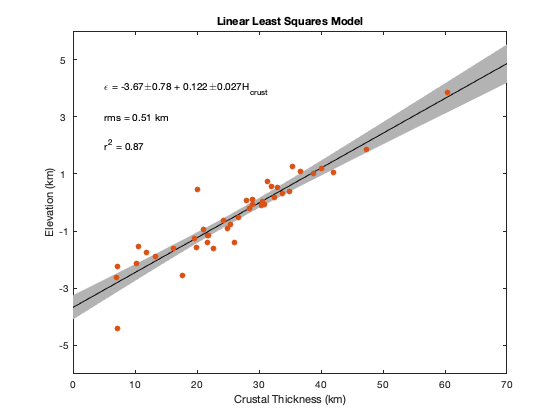


plot_llsq(data.moho_mean,data.elev_mean,m,[0 70]);

% I have taken error bars off of this plot because we are not using the
% data uncertainties to produce this fit.
%errorbar2d(data.moho_mean,data.elev_mean,data.moho_sd,data.elev_sd,'.');

scatter(data.moho_mean,data.elev_mean,'filled');
xlabel('Crustal Thickness (km)');
ylabel('Elevation (km)')

text(5,2,['r^2 = ',num2str(rsq,2)]);
text(5,3,['rms = ',num2str(rms,2),' km']);
set(gca,'Box','on','YTick',[-7:2:5],'YTickLabel',[-7:2:5]);
text(5,4,['\epsilon = ',num2str(m(1,1),3),'\pm',num2str(m(1,2),2),' + ',num2str(m(2,1),3),'\pm',num2str(m(2,2),2),'H_{crust}']);
title('Linear Least Squares Model');

### 6.4.3 Uncertainties in Regression Models

There is an uncertainty in fitting parameters that results from the variability in the data and is propagated through the inversion.  The $\alpha_{95}$ confidence intervals for the regression model parameters can be estimated by


$${\bf m}_{\alpha_{95}} = 1.96\, \mathrm{diag}({\bf C})^{1/2}$$


where ${\bf C}$ is the covariance matrix, ${\bf C} = ({\bf A}^{\text T} {\bf A})^{-1}$.  The factor 1.96 is approximate, scaling the standard deviation to $\alpha_{95}$.

The uncertainty in both the slope and intercept means that there is a range of linear models that fit the data.  Hence the grey bounds in the plot above that define the confidence interval of the inversion model on the plot.  To define these bounds, relative to a point $(\hat{x},\hat{y})$ on the mean regression curve,


$$y_{\alpha_{95}} = \hat{y} \pm P(t_{(1 - \alpha_{95})/2,\nu}) \hat{x} SE$$


where


$$SE = \left(\frac{ ({\bf d} - \hat{\bf d})^{\text{T}}({\bf d} - \hat{\bf d})}{\nu} \right)^{1/2} \left(\frac{1}{N} + \frac{(\hat{x} - \bar{x})^2}{({\bf x} - \bar{x})^{\text{T}}({\bf x} - \bar{x}) } \right)^{1/2}$$


and $P(t_{(1 - \alpha_{95})/2,\nu})$ is the inverse of the $t$-distribution for a confidence value of $\alpha_{95}$ and $\nu = N - M
$ degrees of freedom when $N$ is the number of data and $M$is the number of model parameters.

### 6.4.4 Polynomials and Multivariate Regression

Thus far we have only looked at the equation $y = mx + b$ to fit a model to data.  But there are many instances where we will want to fit more complex models to data.  At this point inversion problems fall into two classes: linear and non-linear.  A generalized linear equation can be formulated as


$$\hat{y} = m_0 + m_1 x_1 + m_2 x_2 + \ldots + m_k x_k$$


We structure the LLSQ problem as


$$\pmatrix{1 & x_{11} & x_{12} & \ldots & x_{1k} \cr 1 & x_{21} & x_{22} & \ldots & x_{2k} \cr \vdots & \vdots & & \ddots & \vdots \cr 1 & x_{N1} & x_{N2}  & \ldots & x_{Nk}} \pmatrix{m_0 \cr m_1 \cr m_2 \cr \vdots \cr m_k} = \pmatrix{y_1 \cr y_2 \cr \vdots \cr y_N}$$


with $N$ data and $k$ variables.

This broad class of equations includes multivariate (equations of more than one variable) regression and polynomials.  In the case of polynomials, the variable $x_i = x^i$, e.g.,

$y = m_0 + m_1 x + m_2 x^2 + \ldots + m_k x^k$.

Even though a polynomial is not a linear function in $x$, it is linear for the purposes of determining the coefficients which are linear.  For the polynomial case, we formulate the problem as


$$\pmatrix{1 & x_1 & x_1^2 & \ldots & x_1^k \cr 1 & x_2 & x_2^2 & \ldots & x_2^k \cr \vdots & \vdots & & \ddots & \vdots \cr 1 & x_N & x_N^2  & \ldots & x_N^k} \pmatrix{m_0 \cr m_1 \cr m_2 \cr \vdots \cr m_k} = \pmatrix{y_1 \cr y_2 \cr \vdots \cr y_N}$$


And the exponents need not be whole numbers, they could be a square root or an inverse function.  For example, specific heat capacity data follow a temperature-dependent relationship that can be approximated by

$C_P = c_0 + c_1 T^{-1/2} + c_2 T^{-2} + c_3 T^{-3}$.

Density can also be formulated as a linear equation as it dependent on the mineralogy of a sample by

$\rho = \rho_1 x_1 + \rho_2 x_2 + \ldots + \rho_k x_k$.

where $\rho_i$ and $x_i$ are the density and modal proportion of mineral $i$, respectively.

## 6.5 Incorporating Uncertainty

### 6.5.1 Weighted Linear Least Squares

For instance, our solution above does not take into account uncertainties in the data and all data are given equal weight.  It is rarely the case with real data that our uncertainties and errors are all the same.  Therefore, we need a way to incorporate these uncertainties by giving greater weight to the more certain data and less weight to the more uncertain data.

To weight the data based on some degree of certainty (reciprocal of uncertainty), we can define a weighting matrix, ${\bf W_d}$, as in terms of the standard deviation of the data, 


$${\bf W_d} = \pmatrix{ w_{1} & 0 & 0 & \dots & 0 \cr 0 & w_{2} & 0 & \dots & 0 \cr 0 & 0 & w_{3} & \dots & 0 \cr \vdots & & & \ddots & \vdots \cr 0 & 0 & 0 & \dots & w_{N} } = \pmatrix{ \sigma_{1}^{-1} & 0 & 0 & \dots & 0 \cr 0 & \sigma_{2}^{-1} & 0 & \dots & 0 \cr 0 & 0 & \sigma_{3}^{-1} & \dots & 0 \cr \vdots & & & \ddots & \vdots \cr 0 & 0 & 0 & \dots & \sigma_{N}^{-1}}$$


Another common weighting is based on the variance, i.e., ${\bf W_d}^2$.  If you weight to the variance, there will be a much stronger reliance on the low uncertainty data.  There is no correct answer to which one should be chosen (sorry, even with math there is not always a clear answer when real data are involved).

To incorporate the uncertainties into a matrix solution, we weight both sides, i.e.,


$${\bf W_d} {\bf A} {\bf m} = {\bf W_d} {\bf d}$$


The weighting matrix is a diagonal matrix (non-zero only on the diagonal) so that ${\bf W_d} {\bf d}$ yields a column vector with the same dimensions as ${\bf d}$.  Following a similar procedure now as we did before we can show that the solution to the weighted LLSQ is given by


$${\bf m} = ({\bf A}^{\text T} {\bf W_d} {\bf A})^{-1} {\bf A}^{\text T} {\bf W_d} {\bf d}$$


The change in formulation also requires us to redefine our misfit,


$$\phi = \left[ \frac{1}{N} ({\bf d} - \hat{\bf d})^{\text{T}} {\bf W_d}^2 ( {\bf d} - \hat{\bf d}) \right]^{1/2}$$


As an example, let us examine the crustal thickness, elevation data again from above.  *Note, this method only incorporates uncertainties in y, not x.*

clear all;

data = readtable('arc_hp.csv');

A = [ones([height(data) 1]) data.moho_mean];

[m,r,rsq,Cw] = wllsq(data.moho_mean,data.elev_mean,1,data.elev_sd);

% RMS misfit
rms = sqrt(sum(r.^2/height(data)));

m,rms,rsq

m =    -3.6379   11.0492
    0.1212    0.3844


rms = 0.0361

rsq = 0.8762

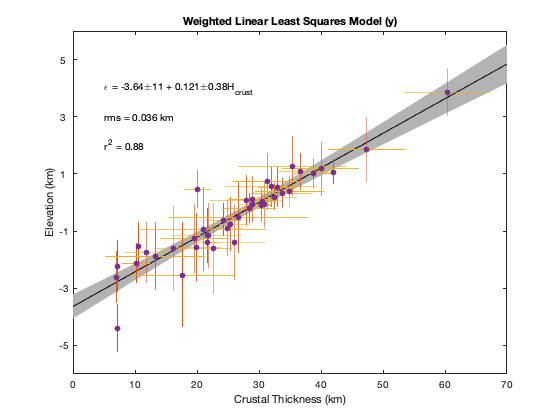


figure;
hold on;

plot_llsq(data.moho_mean,data.elev_mean(:,1),m,[0 70]);

errorbar2d(data.moho_mean,data.elev_mean,data.moho_sd,data.elev_sd,'.');

scatter(data.moho_mean,data.elev_mean,'filled');
xlabel('Crustal Thickness (km)');
ylabel('Elevation (km)')

text(5,2,['r^2 = ',num2str(rsq,2)]);
text(5,3,['rms = ',num2str(rms,2),' km']);
set(gca,'Box','on','YTick',[-7:2:5],'YTickLabel',[-7:2:5]);
text(5,4,['\epsilon = ',num2str(m(1,1),3),'\pm',num2str(m(1,2),2),' + ',num2str(m(2,1),3),'\pm',num2str(m(2,2),2),'H_{crust}']);
title('Weighted Linear Least Squares Model (y)');

Uncertainties in $x$ and $y$ can both be incorporated, but the linear least squares method becomes iterative.  In this case, the method is solved as above first with errors on the data ($y = d$).  Then errors in $x$ are incorporated by creating a new weighting matrix $Wyx = \text{diag}(\{\sigma_y^2 + m_{k-1}^2 \sigma_y^2\}^{-1})$, where $k-1$ is the previously predicted vector of model parameters.

[m,r,rsq,Cw] = wllsq(data.moho_mean,data.elev_mean,data.moho_sd,data.elev_sd);

% RMS misfit
rms = sqrt(sum(r.^2/height(data)));

m,rms,rsq

m =    -3.2538    2.4928
    0.1050    0.1701


rms = 0.0908

rsq = 0.9586

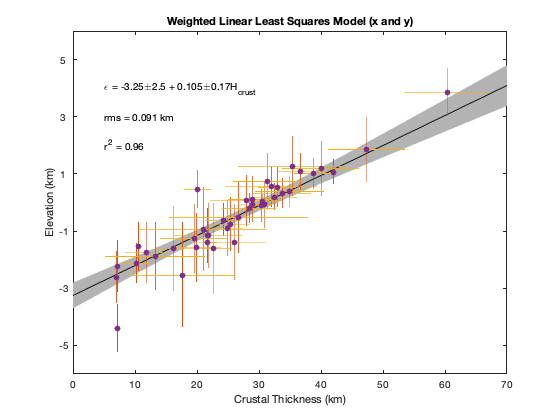


figure;
hold on;

plot_llsq(data.moho_mean,data.elev_mean(:,1),m,[0 70]);

errorbar2d(data.moho_mean,data.elev_mean,data.moho_sd,data.elev_sd,'.');

scatter(data.moho_mean,data.elev_mean,'filled');
xlabel('Crustal Thickness (km)');
ylabel('Elevation (km)')

text(5,2,['r^2 = ',num2str(rsq,2)]);
text(5,3,['rms = ',num2str(rms,2),' km']);
set(gca,'Box','on','YTick',[-7:2:5],'YTickLabel',[-7:2:5]);
text(5,4,['\epsilon = ',num2str(m(1,1),3),'\pm',num2str(m(1,2),2),' + ',num2str(m(2,1),3),'\pm',num2str(m(2,2),2),'H_{crust}']);
title(['Weighted Linear Least Squares Model (x and y)']);

### 6.5.2 Bootstrapping

Bootstrapping belongs to a class of model-fitting techniques called resampling whereby the original sample set is subsampled many times in order to gain a richer understanding of the uncertainties impact on the resulting model.  There are many different formulations for bootstrapping that have various advantages and disadvantages.  But one advantage common to all resampling methods is that they do a better job of estimating uncertainty when the errors are not Gaussian.  Here we will focus on a fairly simple and straightforward version of the technique called residual resampling.

- Fit the data using a least squares model.  Calculate the pseudo-data, $\hat{\bf d}$, and residuals ${\bf \varepsilon} = {\bf d} - \hat{\bf d}$.

- Calculate a set of synthetic data $d_i^* = \hat{d}_i + \varepsilon_j$ where $j$ is randomly chosen from $1,\ldots,N$for every data point.

- Refit a line to these synthetic data and keep a copy of the model parameters.

- Repeat 2 and 3 a large number of times (e.g., $10^3$ to $10^6$)

- Examine the uncertainty on the model parameters and estimate the mean or median values to produce a likely model.

### 6.5.3 Errors on x and y

Most formulations for linear regression assume there are uncertainty on $x$ or $y$ but not both.  It is easy to build weighting on the observations or equations into the solution, but not both.  At present there are not well defined methods to handle errors in both dimensions that isn't brute force.  One way to account for errors in $x$ and $y$ are to use Monte Carlo methods, randomly perturbing $x$ and $y$ and then computing an LLSQ.  Repeat the process a sufficiently large number of times and you can then estimate most likely values for the model parameters and uncertainties from the distribution of results.

## 6.6 Leverage and Outliers

### 6.6.1 Leverage

Leverage is a measure of how far a measurement is from other observations.  It is dependent on the model used to fit the data.

Recall from the LLSQ fit to data, we attempt to fit a linear model to a set of data, $\bf d$, by


$${\bf m} = ({\bf A}^{\text T} {\bf A})^{-1} {\bf A}^{\text T} {\bf d}$$


and then use $\bf m$ to estimate the values of the pseudo-data by $\hat{\bf d} = {\bf A}{\bf m}$.  We can define the projection matrix, $\bf H \equiv {\bf A}({\bf A}^{\text T} {\bf A})^{-1} {\bf A}^{\text T}$, where $\text{diag}\, \bf H$ is the set of leverages for the data and $h_{ii}$ is the $i$-th diagonal asociated with $d_i$.  The larger the value, the greater the leverage on the fit.  You will find that points near the endpoints have greater leverage than those in the middle, which explains why confidence intervals for model fits always have a narrow waist in the middle of the range of ordinate ($x$-axis) values.

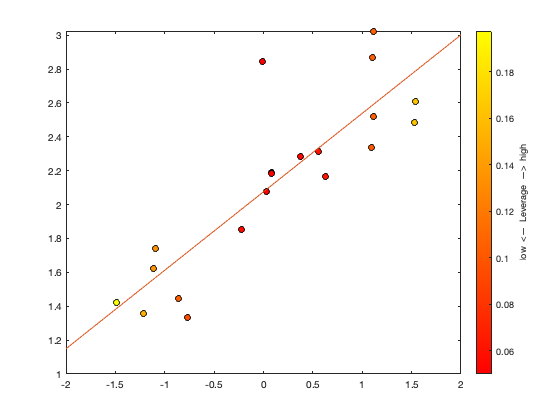

clear all;

% create a random dataset
Nd = 20;
x = randn([Nd 1]);

a = 0.5;
b = 2;
sigmay = 0.2;
noise = sigmay*randn([Nd 1]);
% synthetic data, linear model + noise
y = a*x + b + noise;

% make a point an outlier
ind = randi(Nd,1);

k = 5;
y(ind) = y(ind) + sign(randn(1))*k*sigmay;

A = [ones(size(x)) x];
H = A*inv(A'*A)*A';

m = inv(A'*A)*A'*y;

xl = [floor(min(x)) ceil(max(x))]';
yl = [1 floor(min(x)); 1 ceil(max(x))]*m;

figure;
hold on;
scatter(x,y,40,diag(H),'filled','MarkerEdgeColor','k');
plot(xl,yl,'-');
set(gca,'Box','on');
colormap('autumn');
cb = colorbar;
cb.Label.String = 'low  <—  Leverage  —>  high';

### 6.6.2 Outlier Detection

One method for determining whether a given point is an outlier is known as Cook's distance.  The Cook distance of the fit to each point, $d_i$, is


$$D_i = \frac{\sum_{j = 1}^{N_d} \hat{d}_j - \hat{d}_{j(i)}}{N_m s^2}$$


where $\hat{d}_j$ is the estimated value of the $j$-th data point fit to all the data and $\hat{d}_{j(i)}$ is the estimated value of the $j$-th data point to a fit of the data excluding the $i$-th data point. The number of model parameters is given by $N_m$ and the mean squared error is

$s^2 = \frac{({\bf d - \hat{d}})^{\text{T}}({\bf d - \hat{d}})}{N_d}$.

We can relate the Cook distance to the leverage by

$D_i = \frac{(d_i - \hat{d}_i)^2}{N_m s^2} \left[ \frac{h_{ii}}{(1 - h_{ii})^2} \right]$.

Any point with Cook distance 4 times greater than the mean is often considered influential—values other than 4 may be used—and should be examined in greater detail.

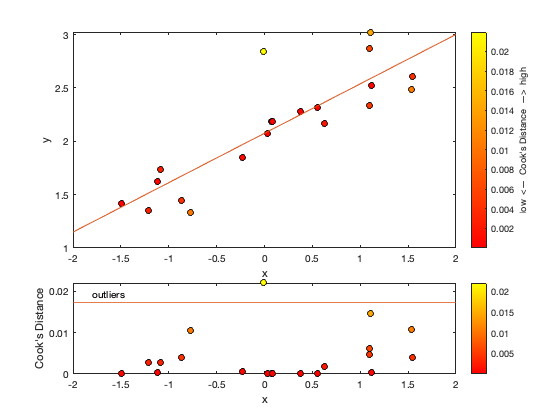

% number of model parameters
Nm = length(m);

% residual vector
r = (y - A*m);

% mean square error
s2 = r'*r/Nm;

D = r.^2/(Nm*s2).*(diag(H)./(1 - diag(H).^2));

figure;
subplot(3,1,1:2);
hold on;
scatter(x,y,40,D,'filled','MarkerEdgeColor','k');
plot(xl,yl,'-');
set(gca,'Box','on');
colormap('autumn');
cb = colorbar;
cb.Label.String = 'low  <—  Cook''s Distance  —>  high';
xlabel('x');
ylabel('y');

subplot(3,1,3);
hold on;
scatter(x,D,40,D,'filled','MarkerEdgeColor','k');
plot(xl,4*mean(D)*[1 1],'-');
text(xl(1)+0.05*diff(xl),4.1*mean(D),'outliers','VerticalAlignment','bottom');
set(gca,'Box','on');
colormap('autumn');
cb = colorbar;
xlabel('x');
ylabel('Cook''s Distance');

A separate measure for outlier detection is known as DFFITS and is defined as

$\text{DFFITS} = \frac{\hat{d}_i - \hat{d}_{i(i)}}{s_{(i)} \sqrt{h_{ii}}$,

where $\hat{d}_i$ and $\hat{d}_{i(i)}$ are the pseudo-data with and without the $i$-th data point included, respectively.  The mean standard error, $s_{(i)}$, is computed without the $i$-th data point.  Values with $\text{DFFITS} > \sqrt{N_m/N_p}$ should be considered for exclusion.

## 6.7 Non-linear Regression

Not all problems we solve satisfy the conditions for linearity or homogeneity, meaning that linear least squares and other linear modeling cannot be used to produce model fits to our data...at least at first.  There are two ways around this problem. The first involves linearizing to then apply the same linear techniques discussed above.  The second method takes advantage of the fact that most processes are smoothly varying and as a result are linear over short distances, which allows for the use of iterative solvers that treat a problem as linear in each iterative step.

#### 6.7.1 Linearizing

Linear equations are a subset of the possible equations one might see in science.  However, there are a great many more that we are likely to come across.  In these cases, we can only use linear least squares models when our equation can be linearized, which is the preferred method to solve the problem as non-linear inverse methods can be time consuming and more unstable.  Now we will look at a problem that can be linearized. The physical model for electrical conductivity of a rock as a function of temperature, we typically use the following non-linear equation:


$$\sigma = \sigma_0 \exp \left( -\frac{H} {kT} \right)$$


where $\sigma_0$ and $H$ are unknown model parameters, $T$ is controlled, and $\sigma$ is the data.  We can still use an LLSQ approach to solve for unknown model parameters because we can transform the non-linear equation above into a linear equation by simply taking the natural logarithm of both sides,


$$\log \sigma = \log \left[ \sigma_0\exp \left( -\frac{H} {kT} \right) \right] = \log \sigma_0 - \frac{H} {kT}$$


This equation can be expressed as a line $y = b + mx$, where $\sigma_0$ is intercept, $-H/k$ is the slope, and $T^{-1}$ is the independent variable.  By redefining one of our model parameters in this form, we achieve a linear equation that can be solved using a LLSQ approach.

However, not all equations can be so easily linearized.  For those cases, we need to develop other inversion techniques.

#### 6.7.2 Newton–Raphson's Method for Locating Roots

There are a number of non-linear inversion methods.  We'll focus on one, Newton's method, which we will explore in a simplified form first before making it a fully-fledged inverse scheme.  If you have taken an introductory course in calculus you may remember the Newton–Raphson method for finding roots (zero-crossings) of functions.  The general idea behind the method locates a root by taking steps progressively closer to the unknown point starting from an initial guess. Following a summary of the method below, we'll extend the method to solve inverse problems.

Take a continuous and differentiable function $y = f(x)$.  Unless the initial guess is sitting at a minimum or maximum, a line drawn tangent to the initial point at $(x_i, f(x_i)$ must intersect a horizontal line running through the root\footnote{The method you may have learned is based on points which sit on the $x$-axis.  I will take a slightly more general approach here, allowing for a root at any arbitrary $y = d$, and hence the horizontal line intersected by the tangent is parallel to the $x$-axis.} (Figure 2).  The equation the tangent line can be given by


$$y - f(x_i) = f\prime(x_i)(x + x_i)$$


where $f\prime(x_i)$ is the slope of the tangent line (derivative of $f(x)$ at $x = x_i$).  The value of $x$ is at this point unknown until we select the value at $y$ that we wish to know the value of $x$.  Suppose we collected data and found$y = d$.  The intersection of our tangent line above and $y = d$ is then said to

occur at $x_{i+1}$ and


$$d - f(x_i) = f\prime(x_i)(x_{i+1} + x_i)$$


Solving for $x_{i+1}$, we find


$$x_{i+1} = x_i + \frac{d - f(x_i)}{f\prime(x_i)}$$


We can define our misfit then as


$$\phi = (d - f(x_{i+1}))^2$$


If our misfit is below our desired precision, then we assume $x_{i+1} \approx x_{\text{true}}$, where $x_{\text{true}}$ is the location of the root.  If not, then we repeat the procedure with a tangent line through $f(x_{i+1})$ and so forth until our misfit falls below the desired precision (or converges, asymptotically approaches some small value).

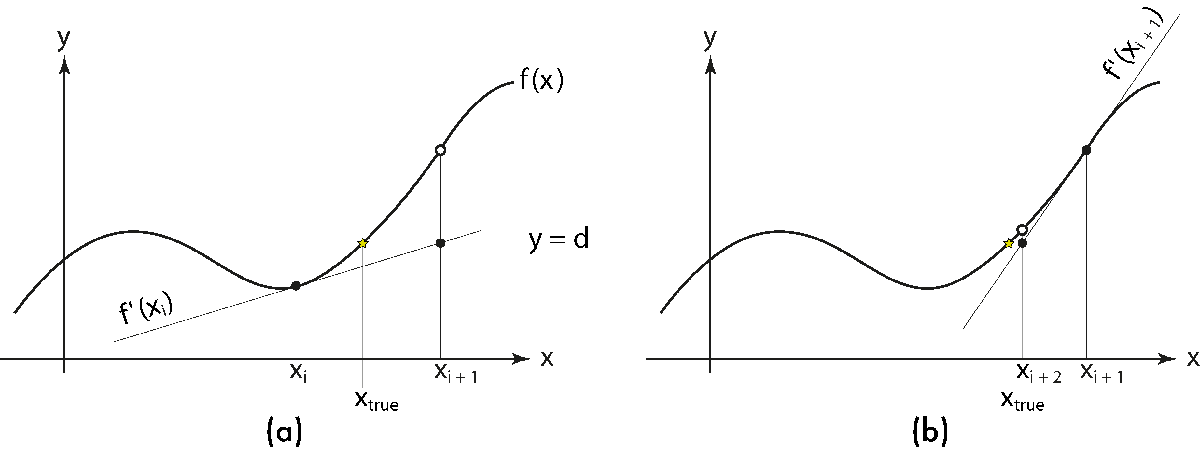

**Figure 2** – *An illustration of the Newton-Raphson method for finding roots, generalized to an arbitrary value of a function (*$y = d$*).  One step (a) leads to the next (b), closer to the unknown point *$x_{\text{true}}$* where the function *$y = f(x)$* intersects *$y = d$*.  The point determined by the Newton-Raphson method can be dependent upon the initial guess.  This can be predicted using this example by imagining a starting point on the opposite side of the minimum as *$x_i$*.*

One more comment on Newton-Raphson's method before we move on because it illustrates an important point with respect to inversions in general.  Where there are multiple crossings at the desired level of the function (e.g., $y = d$ as in Figure 2), the location of the starting point will affect which point the solution converges towards.  Put the starting point on the opposite side of the minimum in Figure 2 and you can by eye or by hand see that a different intersection point will be identified.  This shows why

 we need to be mindful of our initial condition to our iterative inversion schemes.

#### 6.7.3 Newton's Inverse Method

We can extend this method to find the model parameters fit to a set of observed data.  We start each iteration by computing predicted data, $d_m = f(\vec{\xi},\vec{m}_i)$, where $\vec{\xi}$ are the model inputs and $\vec{m}_i$ are the model parameters.  We can construct a derivative of our forward model with respect to the model parameters,


$${\bf J} = \frac{d{\bf f}}{d{\bf m}} = \pmatrix{\frac{\partial f_1}{\partial m_1} & \frac{\partial f_1}{\partial m_2} & \ldots & \frac{\partial f_1}{\partial m_M} \cr \frac{\partial f_2}{\partial m_1} & \frac{\partial f_2}{\partial m_2} & \ldots & \frac{\partial f_2}{\partial m_M} \cr \vdots & & \ddots & \vdots \cr \frac{\partial f_N}{\partial m_1} & \frac{\partial f_N}{\partial m_2} & \ldots & \frac{\partial f_N}{\partial m_M}}$$


where $f_n = f(\xi_n,\vec{m}_i)$.  This matrix is often called the Jacobian or the Fr`é`chet matrix.  Newton–Raphson's method above requires the inverse (or at least the pseudo-inverse) of the Jacobian, which we can construct in a similar manner to the LLSQ recipe, ${\bf J}^+ = ({\bf J}^{\text T} {\bf J})^{-1} {\bf J}^{\text T}$.

Unweighted, ${\bf m}_{i+1} = {\bf m}_i - ({\bf J}^{\text T} {\bf J})^{-1} {\bf J}^{\text T} ({\bf d}_m - {\bf d})$

Weighted, ${\bf m}_{i+1} = {\bf m}_i - ({\bf J}^{\text T} {\bf W} {\bf J})^{-1} {\bf J}^{\text T} {\bf W} ({\bf d}_m - {\bf d})$

The iteration process should continue until the changes in the model parameters is below a given tolerance or the misfit falls below a given threshold.

In the example below, we will use a Newton Method to develop a conductivity relationship for the thermal conductivity of plagioclase solid solutions.  The conductivity of solid solutions as a function of modal proportion of one end-member and temperature (in kelvins) appears to fit a model given by


$$k(\chi,T) = (a + b\chi + c \chi^2)\left(\frac{298}{T}\right)^n$$


where $a$, $b,$ $c$, and $n$ are constants that depend on the mineral.  Because this form is non-linear, we must solve the relationship using an iterative inverse method.  The Fr`é`chet derivatives determined by differentiating with respect to each of the model parameters are as follows:


$$\frac{\partial k}{\partial a} = \left(\frac{298}{T}\right)^n$$



$$\frac{\partial k}{\partial b} = \chi \left(\frac{298}{T}\right)^n$$



$$\frac{\partial k}{\partial c} = \chi^2 \left(\frac{298}{T}\right)^n$$



$$\frac{\partial k}{\partial n} =  (a + b\chi + c \chi^2) \left(\frac{298}{T}\right)^n \log \frac{298}{T}$$


% load conductivity results for known compositions measured under
% temperature conditions
data = load('tc_plag.csv');

X = data(:,1);  % modal proportion anorthite 0 = 100% Ab, 1 = 100% An
T = data(:,2);  % temperature
k = data(:,3);  % thermal conductivity

% starting model
m0 = [2; 0.1; -0.02; 0.8];

% To simplify the code create maximum utility, the Frechet derivatives
% are computed in a separate function that must be written by the user for
% the desired application.  In this case, the Frechet derivatives and
% mathematical model are computed in a function named tcmodel.m.
[m,rms,ci95] = invnewton('tcmodel',[X,T],k,m0)

  Starting Model:   0   RMS: 0.6337
  Iteration:        1   RMS: 0.2974
  Iteration:        2   RMS: 0.1146
  Iteration:        3   RMS: 0.1124
  Iteration:        4   RMS: 0.1124


m =     2.1925
   -2.3374
    2.1731
   -0.2213


rms = 0.1124

ci95 =     0.5162
    2.3248
    2.3299
    0.4393


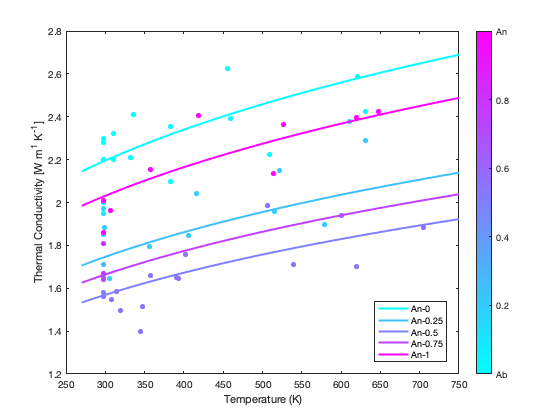


figure;
hold on;

% plot data
scatter(T,k,30,X,'filled');
xlabel('Temperature (K)');
ylabel('Thermal Conductivity [W m^{1} K^{-1}]');

colormap(cool);
cb = colorbar;
cb.Ticks = [0:0.2:1];
cb.TickLabels{1} = 'Ab';
cb.TickLabels{end} = 'An';
set(gca,'Box','on');

% plot model
x = [0:0.25:1];
Temp = [270:10:750]';
C = cool(5);
for i = 1:length(x);
    % compute model
    km = tcmodel(m,[repmat(x(i),[length(Temp) 1]),Temp]);
    p(i) = plot(Temp,km,'Color',C(i,:),'LineWidth',2);
    
    xstr{i} = ['An-',num2str(x(i))];
end

legend(p,xstr,'Location','best');

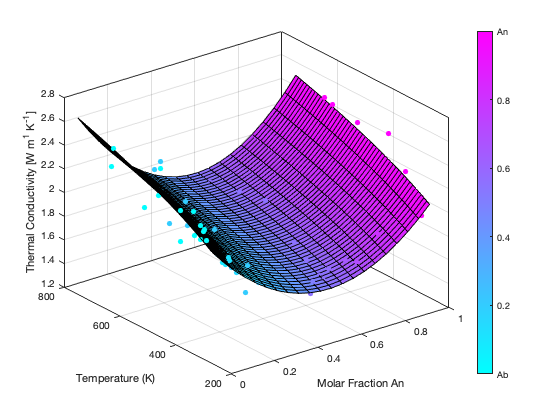

figure;

% plot data
scatter3(X,T,k,30,X,'filled');
ylabel('Temperature (K)');
xlabel('Molar Fraction An');
zlabel('Thermal Conductivity [W m^{1} K^{-1}]')

colormap(cool);
cb = colorbar;
cb.Ticks = [0:0.2:1];
cb.TickLabels{1} = 'Ab';
cb.TickLabels{end} = 'An';
set(gca,'Box','on');
hold on;

% plot model
x = [0:0.05:1];
Temp = [270:10:750]';
C = cool(5);
for i = 1:length(x);
    % compute model
    km(:,i) = tcmodel(m,[repmat(x(i),[length(Temp) 1]),Temp]);
end
surf(x,Temp,km,repmat(x,length(Temp),1));

## 6.8 Regularization

As mentioned near the beginning of this chapter, inversion problems are often unstable.  Regularization is a method that is commonly employed to improve stability by placing a penalty for distance from an a priori model.  However, the model is not really prior knowledge true to the a priori translation so much as a model that is assumed to be somewhat reasonable.